mdl ='Elevation_pod_linear';

io(1)=linio('Elevation_pod_linear/Engine_current_input',1,'input');
io(2)=linio('Elevation_pod_linear/MS_fric_motor5',1,'output');

simulation_POD_Elevation_plant = linearize(mdl,io);

% figure;
% openfig('pod_el_stab_plants.fig')
% ax = gca; 
% h=findobj(gca,'Type','line');


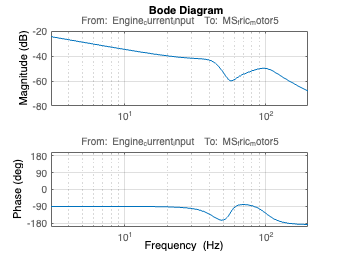

% openfig('pod_el_stab_plants.fig')
% hold on 
opts1=bodeoptions('cstprefs');
opts1.PhaseVisible = 'off';
opts1.YLim={[-80 -20]};
opts1.XLim={[3 200]};

Mag=subplot(2,1,1);bodeplot(simulation_POD_Elevation_plant,opts1); grid on;
set(xlabel(''),'visible','off');
opts2=bodeoptions('cstprefs');
opts2.MagVisible = 'off';
opts2.YLim={[-200 200]};
opts2.XLim={[3 200]};

Phase=subplot(2,1,2);bodeplot(simulation_POD_Elevation_plant,opts2); grid on; title('');